% Mask = imread('..\Data\CenterTestImage.bmp');
Mask = imread('..\Data\CenterComparisonImage.bmp')

Mask = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

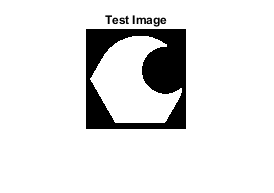

imshow(Mask)
title('Test Image')

lwd=1;
lvls=7;
cbrewmap = flipud(cbrewer('div','Spectral',64));

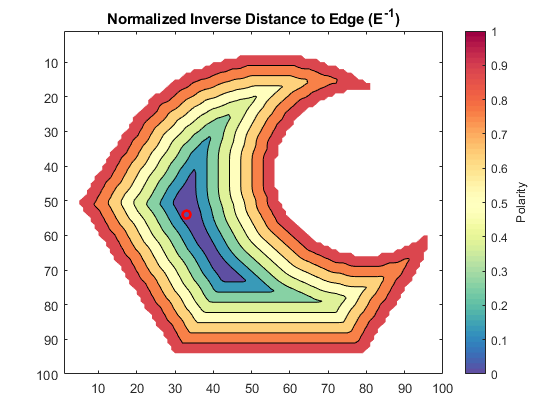

% Normalized Inverse Distance to Edge
figure

[cpts,~,ctrIm] = BWVisualCenter(Mask);
invE = bwdistInv(~Mask);
[NormImage] = NormByBWComp(Mask,invE);
NormImage(~Mask)=NaN;
contourf(NormImage,lvls)
title('Normalized Inverse Distance to Edge (E^{-1})')
hold on
plot(cpts(:,1),cpts(:,2),'or','LineWidth',2)
colormap(cbrewmap)
cax=colorbar;
axis ij
caxis([0 1])
ylabel(cax,'Polarity')

% D/(D+E)
figure
E = bwdist(~Mask);
D = bwdist(ctrIm).*Mask;
val = D./(D+E);
[NormImage] = NormByBWComp(Mask,val);
contourf(NormImage,lvls)
title('D/(D+E)')
hold on
plot(cpts(:,1),cpts(:,2),'or','LineWidth',2)
colormap(cbrewmap)
cax=colorbar;
axis ij
caxis([0 1])
ylabel(cax,'Polarity')
export_fig(gcf,'PolarityMetric','-pdf')

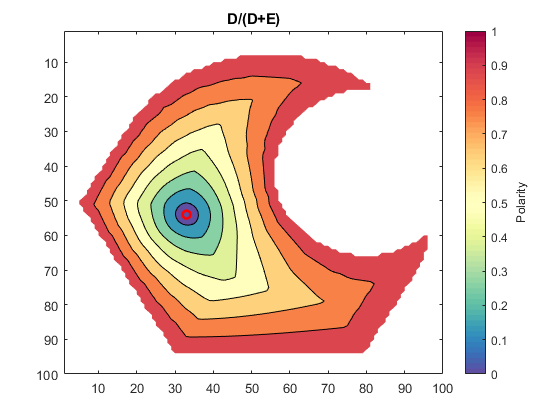


% D/(D+E)
figure
E = bwdist(~Mask);
D = bwdist(ctrIm).*Mask;
val = D;
[NormImage] = NormByBWComp(Mask,val);
NormImage(~Mask)=NaN;
contourf(NormImage,lvls)
title('D')
hold on
plot(cpts(:,1),cpts(:,2),'or','LineWidth',2)
colormap(cbrewmap)
cax=colorbar;
axis ij
caxis([0 1])
ylabel(cax,'Center Distance')
export_fig(gcf,'PolarityMetric_D','-pdf')

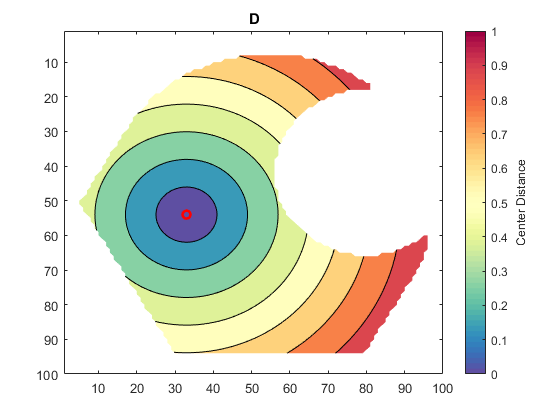


% D/(D+E)
figure
E = bwdist(~Mask);
D = bwdist(ctrIm).*Mask;
val = E;
[NormImage] = NormByBWComp(Mask,val);
NormImage(~Mask)=NaN;
contourf(NormImage,lvls)
title('E')
hold on
plot(cpts(:,1),cpts(:,2),'or','LineWidth',2)
colormap(cbrewmap)
cax=colorbar;
axis ij
caxis([0 1])
ylabel(cax,'Edge Distance')
export_fig(gcf,'PolarityMetric_E','-pdf')

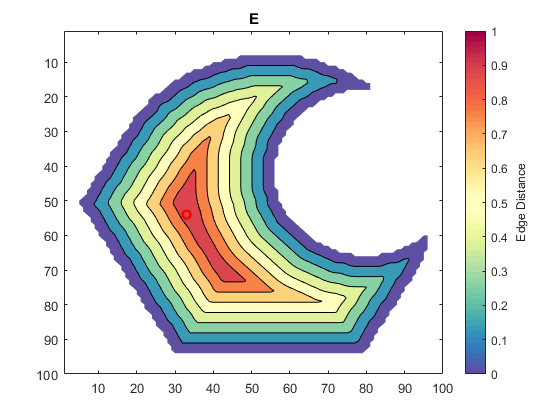

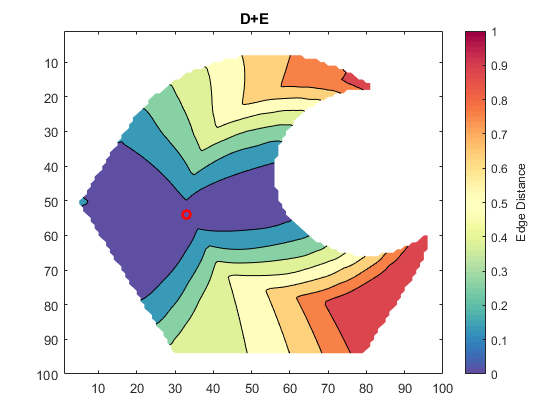


% D/(D+E)
figure
E = bwdist(~Mask);
D = bwdist(ctrIm).*Mask;
val = D+E;
[NormImage] = NormByBWComp(Mask,val);
NormImage(~Mask)=NaN;
contourf(NormImage,lvls)
title('D+E')
hold on
plot(cpts(:,1),cpts(:,2),'or','LineWidth',2)
colormap(cbrewmap)
cax=colorbar;
axis ij
caxis([0 1])
ylabel(cax,'Edge Distance')
export_fig(gcf,'PolarityMetric_DE','-pdf')

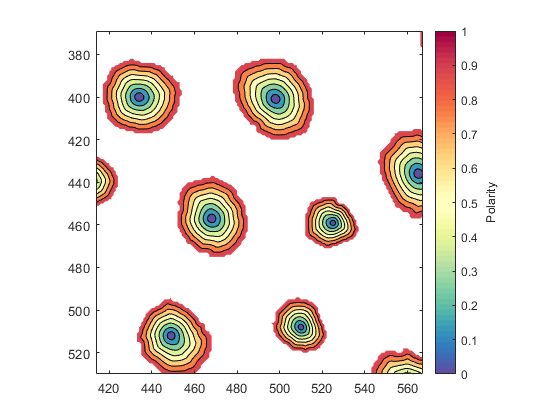

% Edge to center distance map of bone marrow images
HairMask = ~imread('..\Data\Raw_HairCells.bmp');
SupportMask = ~imread('..\Data\RAW_SupportCells.bmp');

cbrewmap = flipud(cbrewer('div','Spectral',64));
figure
contourf(BW_Edge2CtrDist(HairMask),7)
axis ij
axis image
colormap(cbrewmap)
cax=colorbar;
caxis([0 1])
ylabel(cax,'Polarity')

xlim([414 567])
ylim([369 530])

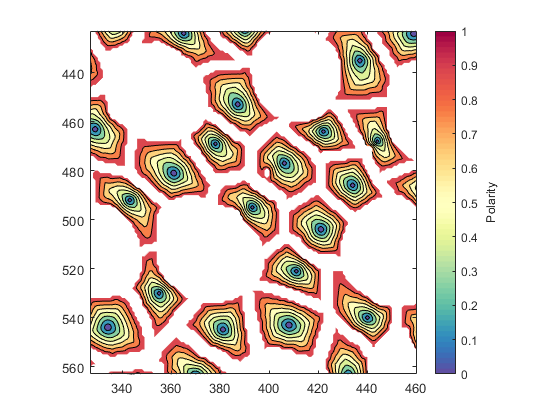

figure
contourf(BW_Edge2CtrDist(SupportMask),7)
axis ij
axis image
colormap(cbrewmap)
cax=colorbar;
caxis([0 1])
ylabel(cax,'Polarity')

xlim([327 460])
ylim([423 563])